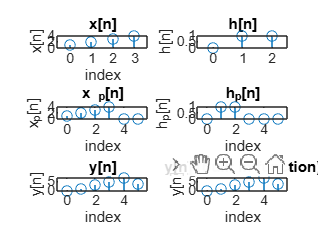

x=input("Enter x[n]:");
h=input("Enter h[n]");
N=length(x);
M=length(h);
L=N+M-1;
X=[x,zeros(1,L-N)];
H=[h,zeros(1,L-M)];
%reversing h[n] without changing h[0]
H_new=[H(1), flip(H(2:L),2)];
y=zeros(1,L);
for i=1:L
    y(i)=sum(X.*circshift(H_new,i-1));
end
subplot(321);
stem(0:N-1,x);
xlabel("index");
ylabel("x[n]");
title("x[n]");
subplot(322);
xlabel("index");
stem(0:M-1,h);
ylabel("h[n]");
title("h[n]");
subplot(323);
stem(0:L-1,X);
xlabel("index");
ylabel("x_p[n]");
title("x _p[n]");
subplot(324);
stem(0:L-1,H);
xlabel("index");
ylabel("h_p[n]");
title("h_p[n]");
subplot(325);
stem(0:L-1,y);
xlabel("index");
ylabel("y[n]");
title("y[n]");
subplot(326);
stem(0:L-1,conv(x,h));
xlabel("index");
ylabel("y[n]");
title("y[n] (built in function)");